# Practica 1: análisis de sonidos

## 1. Carga de señales de audio:

Empecemos cargando una señal de audio en el entorno Matlab:

[audio1,fs]= audioread('pr1_ejercicio1.wav');

Escriba "help audioread" para obtener una descripción de la función *audioread()*  y responda las siguientes preguntas:

- ¿Cuál es la frecuencia de muestreo?, fs.   fs= 16000

- ¿Cuántas muestras, N,  contiene la señal?  N= 45640

- ¿Cuántos bits por muestra se usan para cuantificar de manera discreta la señal original?Bit/sample= 16

- ¿Cuántos canales tiene la señall? (Stereo o mono). Ncanales: 1

- Escriba el código necesario para obtener la longitud de la señal en **segundos**

% INSERTE EL CÓDIGO AQUÍ:
help audioread

 audioread Read audio files
    [Y, FS] = audioread(FILENAME) reads an audio file specified by the
    character vector or string scalar FILENAME, returning the sampled data
    in Y and the sample rate FS, in Hertz.
 
    [Y, FS] = audioread(FILENAME, [START END]) returns only samples START
    through END from each channel in the file.
 
    [Y, FS] = audioread(FILENAME, DATATYPE) specifies the data type format of
    Y used to represent samples read from the file.
    If DATATYPE='double', Y contains double-precision normalized samples.
    If DATATYPE='native', Y contains samples in the native data type
    found in the file.  Interpretation of DATATYPE is case-insensitive and
    partial matching is supported.
    If omitted, DATATYPE='double'.
 
    [Y, FS] = audioread(FILENAME, [START END], DATATYPE);
 
    [Y, FS] = audioread(URL,...) reads the audio file from an Internet URL
 

[audio1,fs]= audioread('pr1_ejercicio1.wav');
audioinfo('pr1_ejercicio1.wav')

ans = struct with fields:
             Filename: 'C:\Users\alumno\Downloads\pr1_ejercicio1.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 16000
         TotalSamples: 48001
             Duration: 3.0001
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


duration = 3.0001 %segs

duration = 3.0001

Puede hacer uso de las funciones *sound *o *soundsc *para escuchar las señales. Utilice la ayuda de Matlab para obtener información sobre estas funciones y responda las siguientes preguntas:

- Especificar las diferencias entre ambas funciones: 

*Soundsc* autoescala el vector de sonido además de reproducirlo.

- ¿Que tipo de sonidos has escuchado? 

## 2. Análisis de sonidos

A continuación, vamos a proceder a analizar en el dominio de tiempo y frecuencia la señal cargada en el apartado anterior. 

## **2.1 Forma de onda.**

Representemos la señal en el dominio del tiempo. Primero, necesitamos definir el eje del tiempo en segundos. Escriba el código necesario para generar el vector t que contiene el tiempo en segundos para cada muestra. Utilice la función plot () para mostrar la señal en el dominio del tiempo (eje x: tiempo, eje y: amplitud). 

% Inserte aquí el código
N=length(audio1);
Ts = 1/fs

Ts = 6.2500e-05

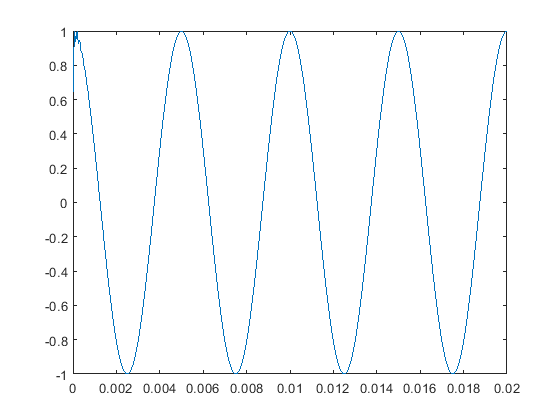

t=0:Ts:Ts*(N - 1);
plot(t,audio1) 
xlim([0 0.02])

Vemos que la señal tiene una gran duración y que la cantidad de muestras es muy grande para observarlas en una figura utilizando un solo plot, pero podemos ver claramente que hay espacios más saturados (a la derecha) que otros (los de la izquierda). Con ayuda de los comandos *axis(),xlim() and ylim() * (utiliza el comando help  para comprender su funcionamiento) se puede elegir de forma sencilla una zona de observación de la señal (hacer un zoom) lo que permite hacer un análisis más detallado de la misma. 					

Utilizando los comandos adecuados visualice en una misma figura, utilizando el comando *subplot*, dos segmentos de 0.02 segundos de duración de la señal, uno al comienzo de la señal y otro al final. 		

En las dos gráficas anteriores tenemos la misma cantidad de muestras, sin embargo, lo que vemos es bastante diferente. 

% Inserte aquí el código
plot(t,audio1) 
xlim([0 0.02])

T=0.01-0.005

T = 0.0050

f=1/T

f = 200

- ¿Cuál es el periodo fundamental y la frecuencia fundamental en cada parte de la señal? 

        T1= 0.0050 ; f1= 200; 

        T2=....; f2= ..... 

Todas estas acciones también se pueden realizar con la aplicación “signal analyzer” de MatLab. Para ello ir al menú APPS y seleccionar la aplicación “signal analyzer”. Cargar la señal audio del Workspace de MatLab al panel de "filter signals". Para ver detalles de la señal seleccionar panner del menú superior y hacerlo muy estrecho para observar los detalles de la señal. 

## **2.2 Análisis del espectro**

A continuación vamos a realizar el análisis del espectro de la señal de audio utilizando la función ver_espectro que se proporciona . Esta función se llama desde MatLab como:

ver_espectro(senal,ventana,Nfft,fs)

Esta función calcula y representa el espectro de una señal almacenada en la variable senal, utilizando el tipo de ventana indicado en ventana y una FFT de Nfft puntos. Use el comando* help ver_espectr*o para más detalles. 

Abre con el editor el fichero ver_espectro.m que contiene la función ver_espectro y analiza con cuidado el código para entender como realiza el cálculo y representación del espectro. 

- Realiza un análisis del espectro de la señal de audio pr1_ejercicio1.wav del apartado anterior utilizando una ventana hamming de 1024 muestras. ¿Qué observas? ¿Es correcto este espectro para el tramo inicial? ¿Y para el tramo final? 									

- Realiza ahora un análisis del espectro de los últimos 0.5 segundos de la señal de audio utilizando una ventana hamming de 1024 muestras. ¿Cuál es la diferencia respecto al resultado anterior? A la vista del espectro, ¿qué señal estamos analizando? ¿Cuál es su frecuencia fundamental? ¿Coincide con la obtenida en el apartado 2.1? 														

-  Prueba distintos tamañosde la ventana de análisis temporal (64, 256, 512, 1024, 2048). ¿De qué duración temporal en segundos es la ventana de 64 muestras? ¿Y la de 1024? 

- Realiza ahora un análisis del espectro del tramo inicial de la señal utilizando los tamaños de ventana del apartado anterior. Utiliza en la representación del espectro un eje logarítmico de frecuencias (modificación en la función ver_espectro). ¿Qué sucede cuando utilizamos una ventana de 64 muestras? ¿Por qué?

-  Vamos a analizar ahora los efectos de distintos tipos de ventana de análisis temporal: rectangular, hamming, hanning. Utiliza en primer lugar una ventana rectangular de 1024 muestras, fíjate en el valor en dB del pico, ¿a qué valor de potencia equivale en unidades naturales? ¿Y el valor de los lóbulos secundarios? Repite para una ventana hanning y comenta las diferencias. 	

- Supón que el enventanado de la señal se realiza con un solapamiento del 50%. Haz un cálculo del número aproximado de ventanas de 1024 muestras que se emplean para analizar 1.5 s de la señal.

% Inserte aquí el código
ver_espectro(audio1,'hamming',1024,fs)

Unrecognized function or variable 'ver_espectro'.

## **2.3 Espectrograma**

El espectrograma es una gráfica que permite visualizar cómo varía el comportamiento espectral de una señal con el tiempo. En el eje horizontal, se representa el paso del tiempo mientras que en el eje vertical, se representa la frecuencia. La mayor o menor concentración de energía se visualiza con la calidez del color; cuanto más cálido, mayor es la energía en esa zona.

En MatLab se dispone de la función *spectrogram* que realiza el cálculo y representación del espectrograma de una señal que se le pasa como parámetro. Analizar y estudiar que hace esta función, cuáles son sus parámetros de entrada y de salida utilizando el comando 

help spectrogram

De acuerdo a lo estudiado en teoría, Hay dos tipos de espectrogramas, dependiendo de la longitud temporal de la ventana. Cuando la ventana temporal es larga, el espectrograma se denomina de banda estrecha mientras que si la ventana temporal es corta, el espectrograma se denomina de banda ancha. Vamos a analizar cada uno de ellos.

Espectrograma de banda estrecha

Inserte las siguientes líneas de código en el espacio a continuación y ejecute la sección. 

% Inserte aquí el código

- ¿Qué se representa al ejecutar el script? A la vista de la gráfica que se obtiene, ¿qué tipo de sonidos contiene la señal almacenada en el vector audio?

- Usando *xlim*, *ylim* o *axis*, haga zoom a la última sección del espectrograma. ¿Cuál es la frecuencia de la señal? 

- Repita el apartado anterior para la parte inicial del espectrograma. 

- Observe qué sucede en torno a 1.5s y relacione este efecto con el tamaño de la ventana

Espectrograma de banda ancha

Emplee ahora ventanas de 128 y de 256 puntos para el cálculo y representación delespectrograma.

- ¿Qué sucede con la precisión de cálculo de las frecuencias de los tonos?

-  ¿Qué sucede en la zona de transición de ambos tonos?

% Inserte aquí el código

Escriba algunas conclusiones explicando qué tipo de ventana usaría para analizar:     

a) Señales con eventos impulsivos o transiciones bruscas.     

b) Componentes tonales. 

## **3. Análisis de una señal de audio con frecuencia fundamental y amplitud variable en el tiempo. **

En esta sección vamos a proceder con el análisis de la señal en el archivo* pr1_ejercicio2.wav*. Escriba el código necesario en los recuadros  y responda las siguientes preguntas. 

- Escuche la señal. ¿Percibe un volumen constante a lo largo de la señal?

% Insertar código aquí

- Calcule a partir de la forma de onda las frecuencias fundamentales de la sección inicial, la sección entre 0,8 y 1 sy la última sección. ¿Qué pasa en el último caso? f1 = ....; f2 = .....; f3 = 

% Insertar código aquí

- Obtenga la frecuencia de la última sección mediante análisis espectral (utilice los parámetros adecuados de la funcion *ver_espectro)*. f = ..... 

% Insertar código aquí

- Repita la última sección para obtener la frecuencia de la primera parte de la señal. 

% Insertar código aquí

- Utilizando el espectrograma (función *spectrogram*) ajusta de forma conveniente los parámetros para su cálculo de forma que puedas obtener las frecuencias fundamentales de cada intervalo.

% Insertar código aquí

## **4. Análisis de señales reales. **

Un análisis correcto de señales de audio reales requiere analizar:

-  La variación de la energía de la señal en el tiempo. Si es más o menos cambiante, si es constante o no. Además es importante identificar en el tiempo periodos derepetición, si existen.

- La variación de la energía en frecuencia. Si hay componentes tonales o no, si existen zonas ruidosas, si hay patrones armónicos o no, etc. También es importante identificar la posición precisa de los tonos en caso de haberlos.

- Variación de la energía en frecuencia a lo largo del tiempo (espectrogramas). Analizar los intervalos temporales con patrones armónicos, los de apariencia ruidosa, con bajas, medias o altas frecuencias. Variación de la frecuencia fundamental a lo largo del tiempo (como la entonación en la voz o la melodía en un instrumento) es otro elemento a tener en consideración.

En los siguientes apartados vamos a analizar una señal de voz femenina  Utilizaremos la metodología estudiada en los anteriores apartados para analizar su contenido frecuencial y temporal.

## 4.1 Características de una voz femenina

Cargue el archivo de audio* pr1_ejercicio3.wav* en el espacio de trabajo de Matlab y obtenga la frecuencia de muestreo, el número de bits por muestreo, la duración de la señal en segundos y el número de canales (estéreo o mono). Escuche la señal. 

Dibuje la señal y usando *xlim *haga zoom en la parte donde está localizado el primer sonido /a/. Para ello puede usar un vector auxiliar para seleccionar solo una parte de las muestras de la señal original. Anote la duración en muestras y ms del sonido /a/. 

% Insertar código aquí

- Observe el patrón cuasi periódico de la señal. ¿Podría estimar la frecuencia fundamental?  fo=.....

    % Insertar código aquí

- Elige una ventana adecuada de muestras del tramo central de la /a/ y visualiza su espectro. ¿Hay componentes tonales?. ¿Y patrones armónicos?

% Insertar código aquí

- Apunta los valores de la frecuencia fundamental (pitch) y de los 5 tonos siguientes, así como sus amplitudes (energía). ¿Son armónicos puros de la frecuencia fundamental?

## 4.2 Representación en tiempo y frecuencia de una señal de voz

1. Calcule y represente un espectrograma utilizando 1024 muestras de ventanas de Hamming (función *spectrogram*).

- ¿Puede distinguir las áreas donde vibran las cuerdas vocales del hablante?

- Expanda la zona temporal de / a /.

- ¿Puedes distinguir los armónicos que has visto en el espectro antes?

- ¿Coinciden las frecuencias con sus estimaciones anteriores?

- ¿Los niveles de los colores corresponden a los picos de energía más altos / más bajos vistos anteriormente en el espectro? Puede utilizar la opción "insertar barra de color".

- Sigue el tono (frecuencia fundamental) y comenta la evolución de la entonación. 

% Insertar código aquí

2. Calcular y representar un espectrograma con ventanas de 128 muestras

- Analizar la evolución de la energía en la banda entre 200 y 700Hz.

- Repita para la banda entre 700 y 3000 Hz. 

% Insertar código aquí

*La evolución de estas 2 bandas (formantes) en el espectrograma de banda ancha nos va indicando el movimiento del tracto vocal cuando pronunciamos vocales. El tracto vocal comprende la cavidadoral (desde la laringe hasta los labios) y la cavidad nasal acoplada a la oral a través del velo y puede considerarse como un filtro con cinco zonas de resonancias (5 formantes) por el que pasa el aire que viene de los pulmones. Si las cuerdas vocales están vibrando,aparecen las rayas horizontales en el espectrograma de banda estrecha. Para las vocales, los formantes principales están en las bandas analizadas anteriormente. En la siguiente figura, se observan unos promedios de las frecuencias de los dos primeros formantes de las cinco vocales del español*